# Analytically Solving 2D Steady-State Heat Equation on Thin, Rectangular Plate

This example finds the temperature distribution of a 2D rectangular plate by solving the governing partial differential equation using the method of separation of variables. This example uses Symbolic Math Toolbox™ to analytically solve the problem of heat transfer of a rectangular plate as discussed in [1].

**Before getting started:**

Please select "Output inline" button on the right scroll bar or under the "View" tab to display the outputs inline with the code blocks (see the image below for further details):

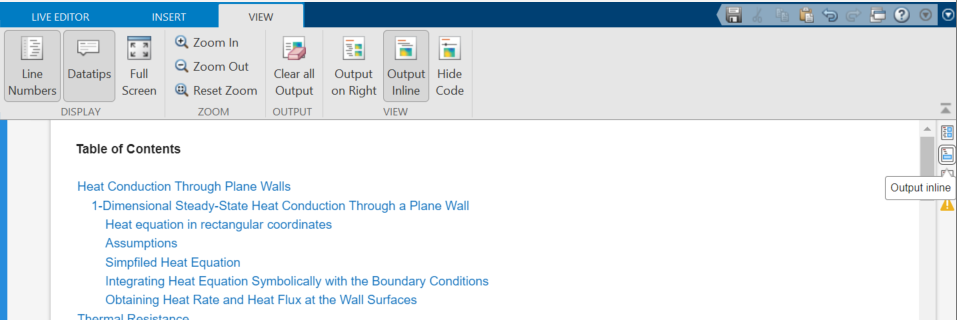

## Problem Description

We will derive the analytical solution to the 2D, steady-state heat equation with no internal heat generation and thermal conductivity $k=1$. The heat equation for this case simplifies to:


$$\frac{\partial^2 T}{\partial x^2} + \frac{\partial^2 T}{\partial y^2} = 0$$


We will consider a rectangular domain of length $L$ and width $W$. The temperatures are on all edges of the rectangle. The top edge of the rectangle is fixed at constant temperature $T_2$, whereas all of the other sides are fixed at constant temperature $T_1$, where $T_2 > T_1$, like so:

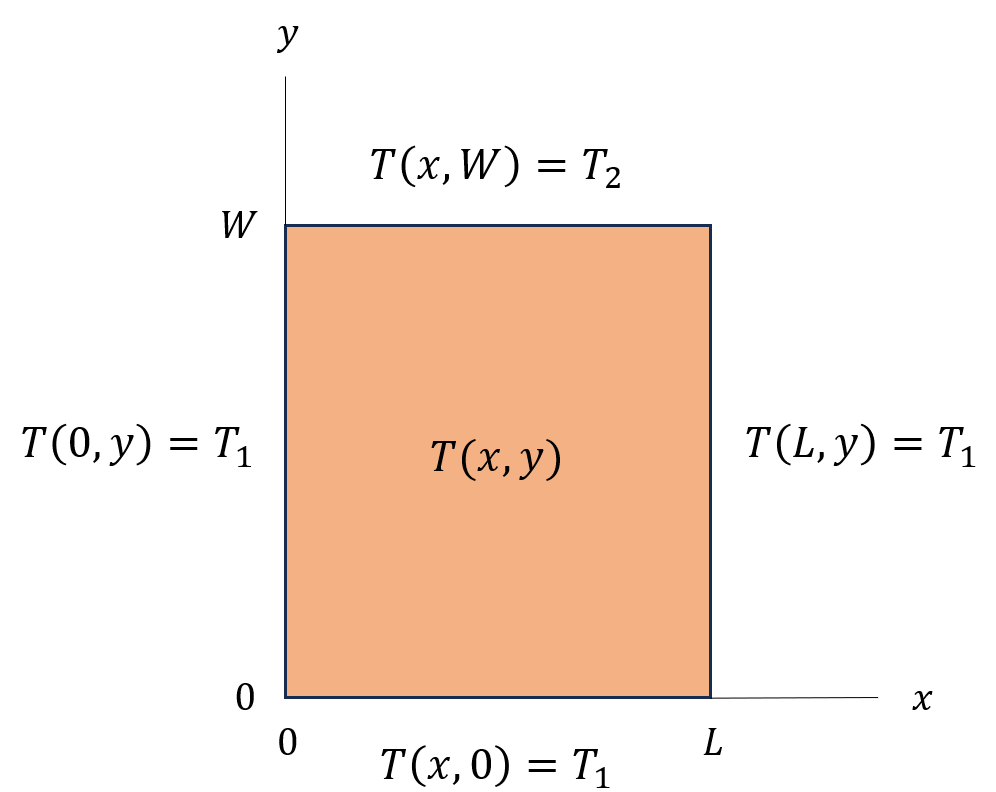

## Change of Variables

To simplify the calculations, introduce the change of variables

$\Theta := \frac{T-T_1}{T_2-T_1}$.

The boundary conditions then become:


$$T = T_1 \rightarrow \Theta = 0$$



$$T=T_2 \rightarrow \Theta = 1$$


Applying the chain rule to the heat equation we have:


$$\frac{\partial^2 T}{\partial x^2} + \frac{\partial^2 T}{\partial y^2} = \frac{\partial}{\partial x}\left(\frac{\partial T}{\partial x}\right) + \frac{\partial}{\partial y}\left(\frac{\partial T}{\partial y}\right) = \frac{\partial}{\partial x}\left(\frac{\partial T}{\partial \Theta}\frac{\partial\Theta}{\partial x}\right) + \frac{\partial}{\partial y}\left(\frac{\partial T}{\partial \Theta}\frac{\partial\Theta}{\partial y}\right) = 0$$
 

Plugging in our defintion of $\Theta$, the heat equation reduces to

syms x y T T1 T2 Theta(x,y)
assume(T2>T1)
ThetaForm = (T-T1)/(T2-T1)

$$ThetaForm = -\frac{T-T_{1}}{T_{1}-T_{2}}$$

TForm = isolate(Theta == ThetaForm, T)

$$TForm = T=T_{1}-T_{1}\,\Theta \left(x,y\right)+T_{2}\,\Theta \left(x,y\right)$$

dTdTheta = diff(rhs(TForm), Theta);

dThetadx = diff(Theta, x);
dThetady = diff(Theta, y);

dimensionlessEqn = diff(dTdTheta*dThetadx,x) + diff(dTdTheta*dThetady,y) == 0

$$dimensionlessEqn(x, y) = -\left(T_{1}-T_{2}\right)\,\frac{\partial^{2}}{\partial x^{2}}\Theta \left(x,y\right)-\left(T_{1}-T_{2}\right)\,\frac{\partial^{2}}{\partial y^{2}}\Theta \left(x,y\right)=0$$

eqMain = simplify(dimensionlessEqn)

$$eqMain(x, y) = \frac{\partial^{2}}{\partial x^{2}}\Theta \left(x,y\right)+\frac{\partial^{2}}{\partial y^{2}}\Theta \left(x,y\right)=0$$

## Method of Separation of Variables

We will now apply separation of variables to solve the equation

$\frac{\partial^2\Theta}{\partial x^2} + \frac{\partial^2\Theta}{\partial y^2} = 0$.

In the method of separation of variables, we assume that the solution $\Theta$ is a product of two univariate functions, i.e.

$\Theta(x,y) = X(x)Y(y)$.

syms X(x) Y(y)
syms L W positive

eqMain = -1*isolate(eqMain,diff(Theta,x,x))

$$eqMain = -\frac{\partial^{2}}{\partial x^{2}}\Theta \left(x,y\right)=\frac{\partial^{2}}{\partial y^{2}}\Theta \left(x,y\right)$$

eqTheta = Theta(x,y) == X(x)*Y(y)

$$eqTheta = \Theta \left(x,y\right)=X\left(x\right)\,Y\left(y\right)$$

eqMain = subs(eqMain,lhs(eqTheta),rhs(eqTheta))

$$eqMain = -Y\left(y\right)\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)=X\left(x\right)\,\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)$$

Divide both sides of the equaton by the product $X(x)Y(y)$

eqMain = eqMain/Y(y)/X(x)

$$eqMain = -\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}$$

The only way for this equation to hold is if both sides are equal to a positive constant, which for convenience we call $\lambda^2$:

syms lambda real
eq1(x) = lhs(eqMain) == lambda^2

$$eq1(x) = -\frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\lambda^{2}$$

eq2(y) = rhs(eqMain) == lambda^2

$$eq2(y) = \frac{\frac{\partial^{2}}{\partial y^{2}}Y\left(y\right)}{Y\left(y\right)}=\lambda^{2}$$

Solve each differential equation to get the general solutions. 

Xsol(x) = dsolve(eq1)

$$Xsol(x) = C_{1}\,\cos\left(\lambda \,x\right)-C_{2}\,\sin\left(\lambda \,x\right)$$

Ysol(y) = dsolve(eq2)

$$Ysol(y) = C_{1}\,{\mathrm{e}}^{\lambda \,y}+C_{2}\,{\mathrm{e}}^{-\lambda \,y}$$

## Apply Boundary Conditions to Find Mode Solutions

Although the Symbolic Math Toolbox returns $C_1$ and $C_2$ in both $Xsol$ and $Ysol$, these constants are not necessarily related. Substitute in $A,B,C,D$ to show that these are different constants. We will use the boundary conditions to solve for these different constants. 

syms C1 C2 A B
Xsol = subs(Xsol,[C1 C2], [A B])

$$Xsol(x) = A\,\cos\left(\lambda \,x\right)-B\,\sin\left(\lambda \,x\right)$$

syms C D 
Ysol = subs(Ysol,[C1 C2], [C D])

$$Ysol(y) = C\,{\mathrm{e}}^{\lambda \,y}+\text{D}\,{\mathrm{e}}^{-\lambda \,y}$$

Use the boundary condition $\Theta(x=0,y) = X(0)Y(y) = 0$ to solve for $A$:

Asol = solve(Xsol(0) == 0, A)

$$Asol = 0$$

Xsol = subs(Xsol,A,Asol)

$$Xsol(x) = -B\,\sin\left(\lambda \,x\right)$$

Use the boundary condition $\Theta(x,y=0) = X(x)Y(0) = 0$ to solve for $C$:

Csol = solve(Ysol(0)==0, C)

$$Csol = -\text{D}$$

Ysol = subs(Ysol,C,Csol)

$$Ysol(y) = \text{D}\,{\mathrm{e}}^{-\lambda \,y}-\text{D}\,{\mathrm{e}}^{\lambda \,y}$$

Ysol = collect(Ysol,D)

$$Ysol(y) = \left({\mathrm{e}}^{-\lambda \,y}-{\mathrm{e}}^{\lambda \,y}\right)\,\text{D}$$

Notice that $e^{-\lambda y} - e^{\lambda y}$ can be written in terms of $\sinh$:

Ysol = rewrite(Ysol,'sinh')

$$Ysol(y) = -2\,\text{D}\,\sinh\left(\lambda \,y\right)$$

Use the boundary condition $\Theta(x=L,y)=X(L)Y(y)=0$ to solve for the constant $\lambda$:

[lambdaSol,params,conds] = solve(Xsol(L)==0,lambda,ReturnConditions=true)

$$lambdaSol = \frac{\pi \,k}{L}$$

$$params = k$$

$$conds = k\in \mathbb{Z}\wedge B\neq 0$$

Plugging these back into our separation of variables assumption for $\Theta$ we have:

eqTheta = subs(eqTheta,{X Y},{Xsol Ysol})

$$eqTheta = \Theta \left(x,y\right)=2\,B\,\text{D}\,\sin\left(\lambda \,x\right)\,\sinh\left(\lambda \,y\right)$$

Lump the constants into one constant that depends explicitly on the parameter $k$: 

syms C(k) 
eqTheta = subs(eqTheta,{2*B*D lambda}, {C(k) lambdaSol})

$$eqTheta = \Theta \left(x,y\right)=C\left(k\right)\,\sin\left(\frac{\pi \,k\,x}{L}\right)\,\sinh\left(\frac{\pi \,k\,y}{L}\right)$$

## Compute Integral of Orthogonal Functions

Because the equation we are solving is linear, the solution can be written as a linear combination of the modes $k \in \mathbb{Z}$. 

Theta_k(x,y,k) = rhs(eqTheta)

$$Theta\_k(x, y, k) = C\left(k\right)\,\sin\left(\frac{\pi \,k\,x}{L}\right)\,\sinh\left(\frac{\pi \,k\,y}{L}\right)$$

Theta_sol = symsum(Theta_k,k,-Inf,Inf)

$$Theta\_sol(x, y) = \left(\sum_{k=0}^{\infty }C\left(k\right)\,\sin\left(\frac{\pi \,k\,x}{L}\right)\,\sinh\left(\frac{\pi \,k\,y}{L}\right)\right)+\left(\sum_{k=1}^{\infty }C\left(-k\right)\,\sin\left(-\frac{\pi \,k\,x}{L}\right)\,\sinh\left(-\frac{\pi \,k\,y}{L}\right)\right)$$

Because $\sin$ and $\sinh$ are odd functions, we notice that $\Theta_k$ + $\Theta_{-k}$ will simplify:

Theta_k2(x,y,k) = simplify(Theta_k(x,y,k)+Theta_k(x,y,-k))

$$Theta\_k2(x, y, k) = \sin\left(\frac{\pi \,k\,x}{L}\right)\,\sinh\left(\frac{\pi \,k\,y}{L}\right)\,\left(C\left(-k\right)+C\left(k\right)\right)$$

Rewrite the general solution by summing all of these modes. Here, define another coefficient $G(k):=C(-k)+C(k)$. Note that $k = 0$ implies that $\Theta(x,y) = 0$. Therefore, take the summation of the $k$ indices from 1 to $\infty$.

syms G(k)
Theta_sol = symsum(subs(Theta_k2,C(-k)+C(k),G(k)),k,1,Inf)

$$Theta\_sol(x, y) = \sum_{k=1}^{\infty }\sin\left(\frac{\pi \,k\,x}{L}\right)\,G\left(k\right)\,\sinh\left(\frac{\pi \,k\,y}{L}\right)$$

Plug in the last boundary condition, $\Theta(x,y=W) = 1$ to find the value of the constant $G(k)$ for $k=1,2,\dots$. 

ThetaBound = Theta_sol(x,W) == 1

$$ThetaBound = \sum_{k=1}^{\infty }\sinh\left(\frac{\pi \,W\,k}{L}\right)\,\sin\left(\frac{\pi \,k\,x}{L}\right)\,G\left(k\right)=1$$

We use the fact that $g_m(x) = \sin\left(\frac{m\pi x}{L}\right)$ is a family of orthogonal functions for $m \in \{1,2,\dots\}$. That is, for $m, k\in\{1,2,\dots\}$, $m\neq k$, we have

$\int_a^b g_m(x) g_k(x) dx = 0$.

syms m k positive integer
ThetaBound = ThetaBound*sin((m*pi*x)/L) % multiply both sides of the equation by g_m(x)

$$ThetaBound = \sin\left(\frac{\pi \,m\,x}{L}\right)\,\left(\sum_{k=1}^{\infty }\sinh\left(\frac{\pi \,W\,k}{L}\right)\,\sin\left(\frac{\pi \,k\,x}{L}\right)\,G\left(k\right)\right)=\sin\left(\frac{\pi \,m\,x}{L}\right)$$


ThetaBound = int(lhs(ThetaBound),x,0,L) == int(rhs(ThetaBound),x,0,L)

$$ThetaBound = \int_{0}^{L}\sin\left(\frac{\pi \,m\,x}{L}\right)\,\left(\sum_{k=1}^{\infty }\sinh\left(\frac{\pi \,W\,k}{L}\right)\,\sin\left(\frac{\pi \,k\,x}{L}\right)\,G\left(k\right)\right)\mathrm{d}x=\frac{2\,L\,{\sin\left(\frac{\pi \,m}{2}\right)}^{2}}{m\,\pi }$$

This integration involves a symbolic summation series that uses the `symsum` function. The Symbolic Math Toolbox does not find this integral explicitly, so you need to investigate the integral of each summation term on the left-side of the above equation. Extract each symbolic summation term that has the indices $m$ and $k$. Define this term as a new expression. You can use copy and paste from the output above when defining this expression manually.

expr_temp = sin((sym(pi)*m*x)/L)*sinh((sym(pi)*W*k)/L)*G(k)*sin((sym(pi)*k*x)/L)

$$expr\_temp = \sinh\left(\frac{\pi \,W\,k}{L}\right)\,\sin\left(\frac{\pi \,k\,x}{L}\right)\,G\left(k\right)\,\sin\left(\frac{\pi \,m\,x}{L}\right)$$

expr_int = int(expr_temp,x,0,L)

$$expr\_int = \left\{ \begin{array}{cl} \frac{L\,\sinh\left(\frac{\pi \,W\,m}{L}\right)\,G\left(m\right)}{2} & \text{ if }k=m\\ 0 & \text{ if }k\neq m\\ \frac{\pi \,0^{m-k}\,\sinh\left(W\,k\right)\,G\left(k\right)}{2} & \text{ if }k\leq m\wedge L=\pi \\ \frac{\pi \,0^{k-m}\,\sinh\left(W\,k\right)\,G\left(k\right)}{2} & \text{ if }m\leq k\wedge L=\pi \end{array}\right.$$

Here we can see that all of these integral are 0 except for when $k = m$. Use the same integrand as before, but this type substitute $k = m$:

expr_temp2 = subs(expr_temp,k,m)

$$expr\_temp2 = \sinh\left(\frac{\pi \,W\,m}{L}\right)\,{\sin\left(\frac{\pi \,m\,x}{L}\right)}^{2}\,G\left(m\right)$$

expr_int2 = int(expr_temp2,x,0,L)

$$expr\_int2 = \sinh\left(\frac{\pi \,W\,m}{L}\right)\,G\left(m\right)\,\left(\frac{L}{2}-\frac{L\,\sin\left(2\,\pi \,m\right)}{4\,m\,\pi }\right)$$

Solve for $G(m)$ by using the boundary condition and simplifying the result:

ThetaBound = expr_int2 == rhs(ThetaBound)

$$ThetaBound = \sinh\left(\frac{\pi \,W\,m}{L}\right)\,G\left(m\right)\,\left(\frac{L}{2}-\frac{L\,\sin\left(2\,\pi \,m\right)}{4\,m\,\pi }\right)=\frac{2\,L\,{\sin\left(\frac{\pi \,m}{2}\right)}^{2}}{m\,\pi }$$

ThetaBound = simplify(ThetaBound)

$$ThetaBound = {\left(-1\right)}^{m+1}\,{\left({\left(-1\right)}^{m}-1\right)}^{2}=\pi \,m\,\sinh\left(\frac{\pi \,W\,m}{L}\right)\,G\left(m\right)$$

ThetaBound = isolate(ThetaBound,G(m))

$$ThetaBound = G\left(m\right)=\frac{{\left(-1\right)}^{m+1}\,{\left({\left(-1\right)}^{m}-1\right)}^{2}}{m\,\pi \,\sinh\left(\frac{\pi \,W\,m}{L}\right)}$$

Plug this solution back into the series solution, using the series index $k$:

ThetaBound = subs(ThetaBound,m,k);
Theta_sol = subs(Theta_sol,G,rhs(ThetaBound))

$$Theta\_sol(x, y) = \frac{\sum_{k=1}^{\infty }\frac{{\left(-1\right)}^{k+1}\,\sin\left(\frac{\pi \,k\,x}{L}\right)\,\sinh\left(\frac{\pi \,k\,y}{L}\right)\,{\left({\left(-1\right)}^{k}-1\right)}^{2}}{k\,\sinh\left(\frac{\pi \,W\,k}{L}\right)}}{\pi }$$

## Plot analytical solution

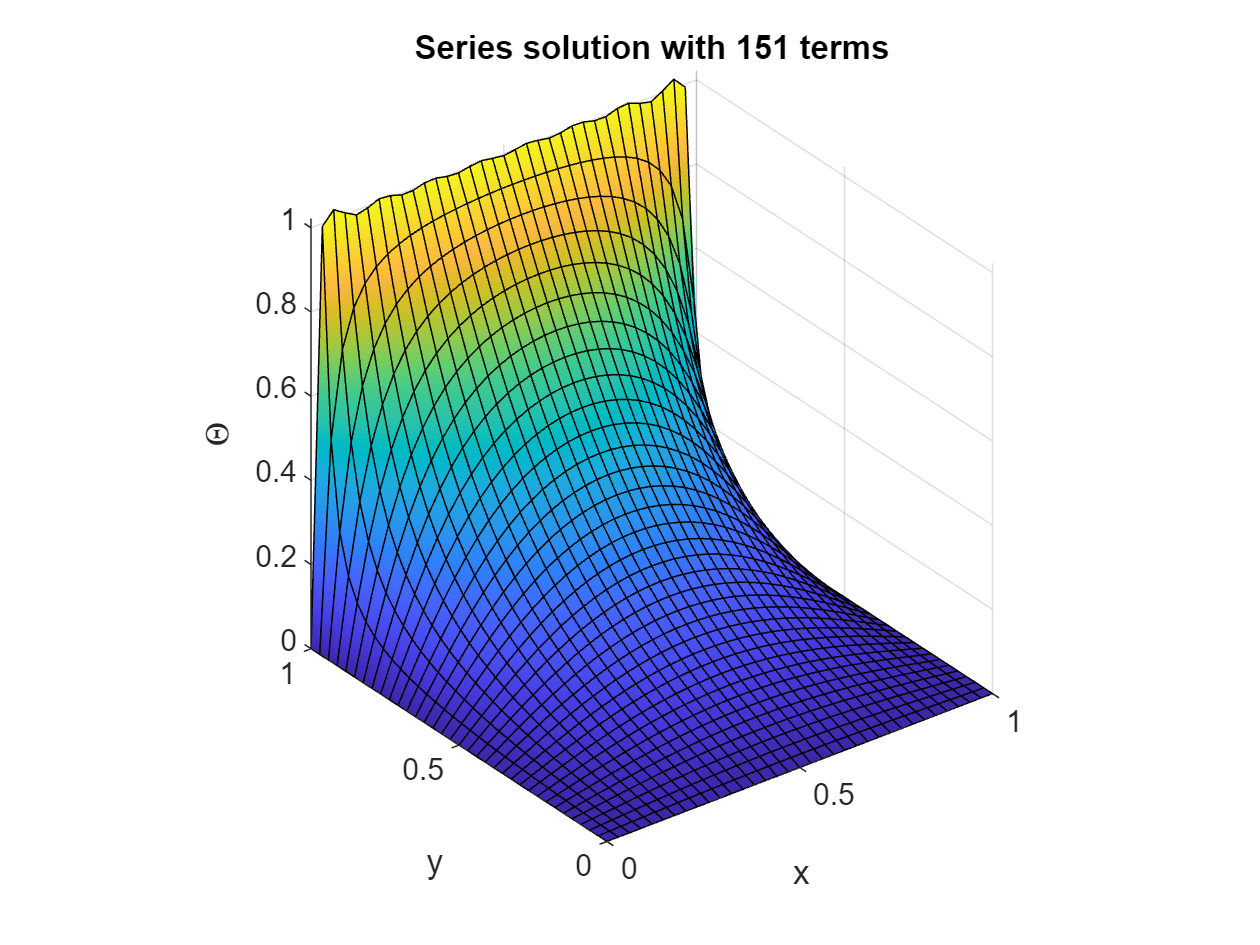

% Plot the result as in Fig 12.1-1 of Reference [1]
b = 151;
Theta_sol(x,y) = symsum(((-sym(1))^(k + 1)*sin((sym(pi)*k*x)/L)*sinh((sym(pi)*k*y)/L)*((-sym(1))^k - 1)^2)/(k*sinh((sym(pi)*W*k)/L)), k, 1, b)/sym(pi);
Theta_sol = subs(Theta_sol,[L W],[1 1]);

digits(2)
Theta_sol_approx = vpa(Theta_sol);

fsurf(Theta_sol_approx,[0 1 0 1])
xlabel('x')
ylabel('y')
zlabel('$\Theta$','Interpreter','latex')
title(sprintf('Series solution with %d terms',b))
axis equal

## Compare with Numerical Solution

Set up and solve the problem in the Partial Differential Equation Toolbox™. 

Create the unit square geometry

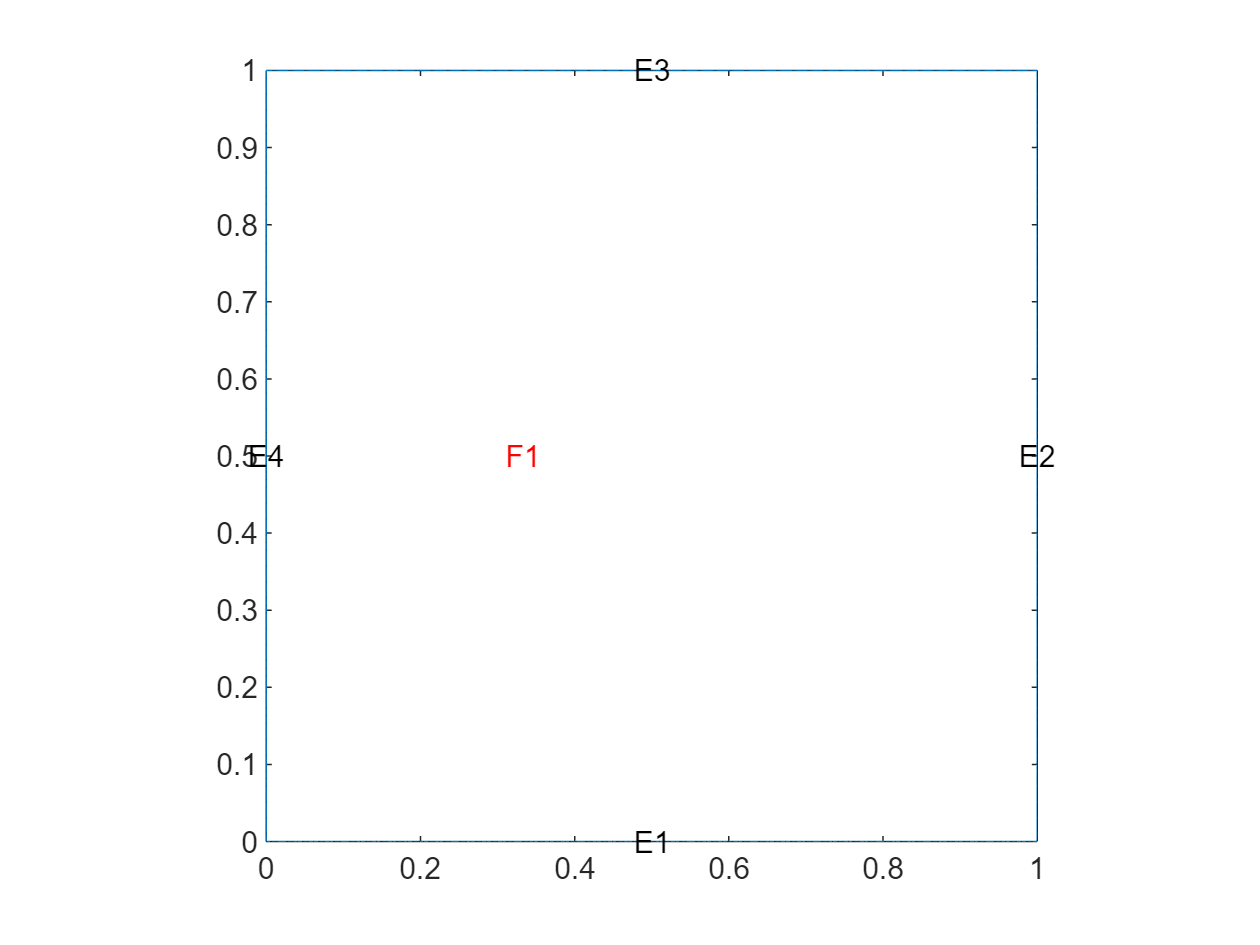

gd = [3; 4; 0; 1; 1; 0; 0; 0; 1; 1];
ns = char('D');  % Name the Regions
ns = ns';
sf = 'D';    %Set the formula
dl = decsg(gd,sf,ns);    

% visualize the geometry
pdegplot(dl,'EdgeLabels', 'on', 'FaceLabels', 'on');

Create the steady-state thermal model

thermalModel = femodel("AnalysisType","thermalSteady","Geometry",dl);

Define the boundary conditions

thermalModel.EdgeBC(1) = edgeBC("Temperature",0); % set the bottom edge to 0
thermalModel.EdgeBC(2) = edgeBC("Temperature",0); % set the right edge to 0
thermalModel.EdgeBC(4) = edgeBC("Temperature",0); % set the left edge to 0
thermalModel.EdgeBC(3) = edgeBC("Temperature",1); % set the top edge to 1

Define the material properties

thermalModel.MaterialProperties = materialProperties("ThermalConductivity",1);

Generate the mesh

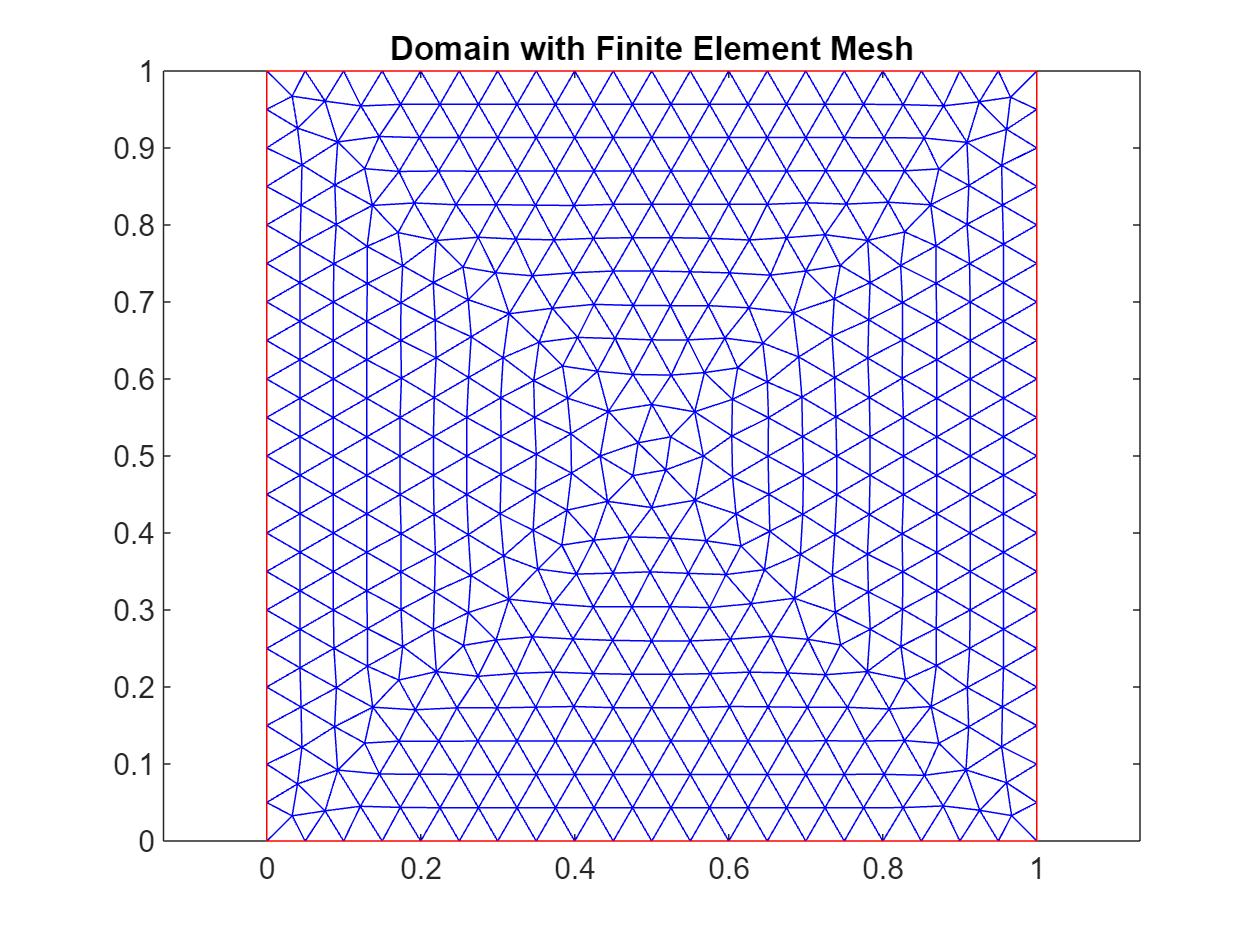

thermalModel = generateMesh(thermalModel,"Hmax",0.05);
% Visualize the mesh
pdemesh(thermalModel); 
% axis equal
title("Domain with Finite Element Mesh")

Solve and plot solution

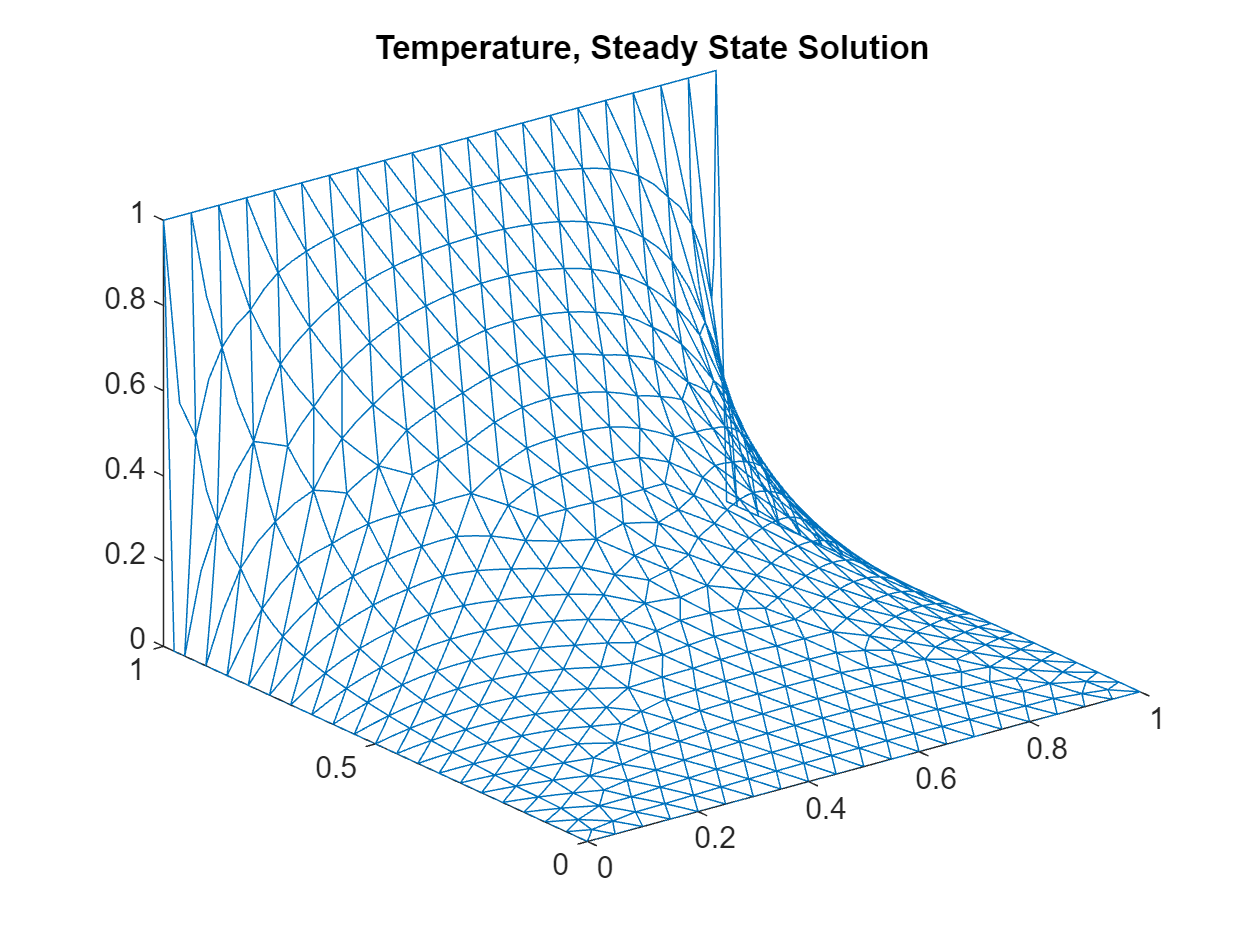

results = solve(thermalModel);
T = results.Temperature;
pdeplot(results.Mesh,"ZData",T); 
% axis equal
title("Temperature, Steady State Solution")

## References

[1] Frank P. Incropera, David P. DeWitt, Theodore L. Bergman, Adrienne S. Lavine. (2007). "Fundamentals of Heat and Mass Transfer." 6th Edition, John Wiley & Sons, Example on p. 203–207.

*Copyright 2024 The MathWorks, Inc.*